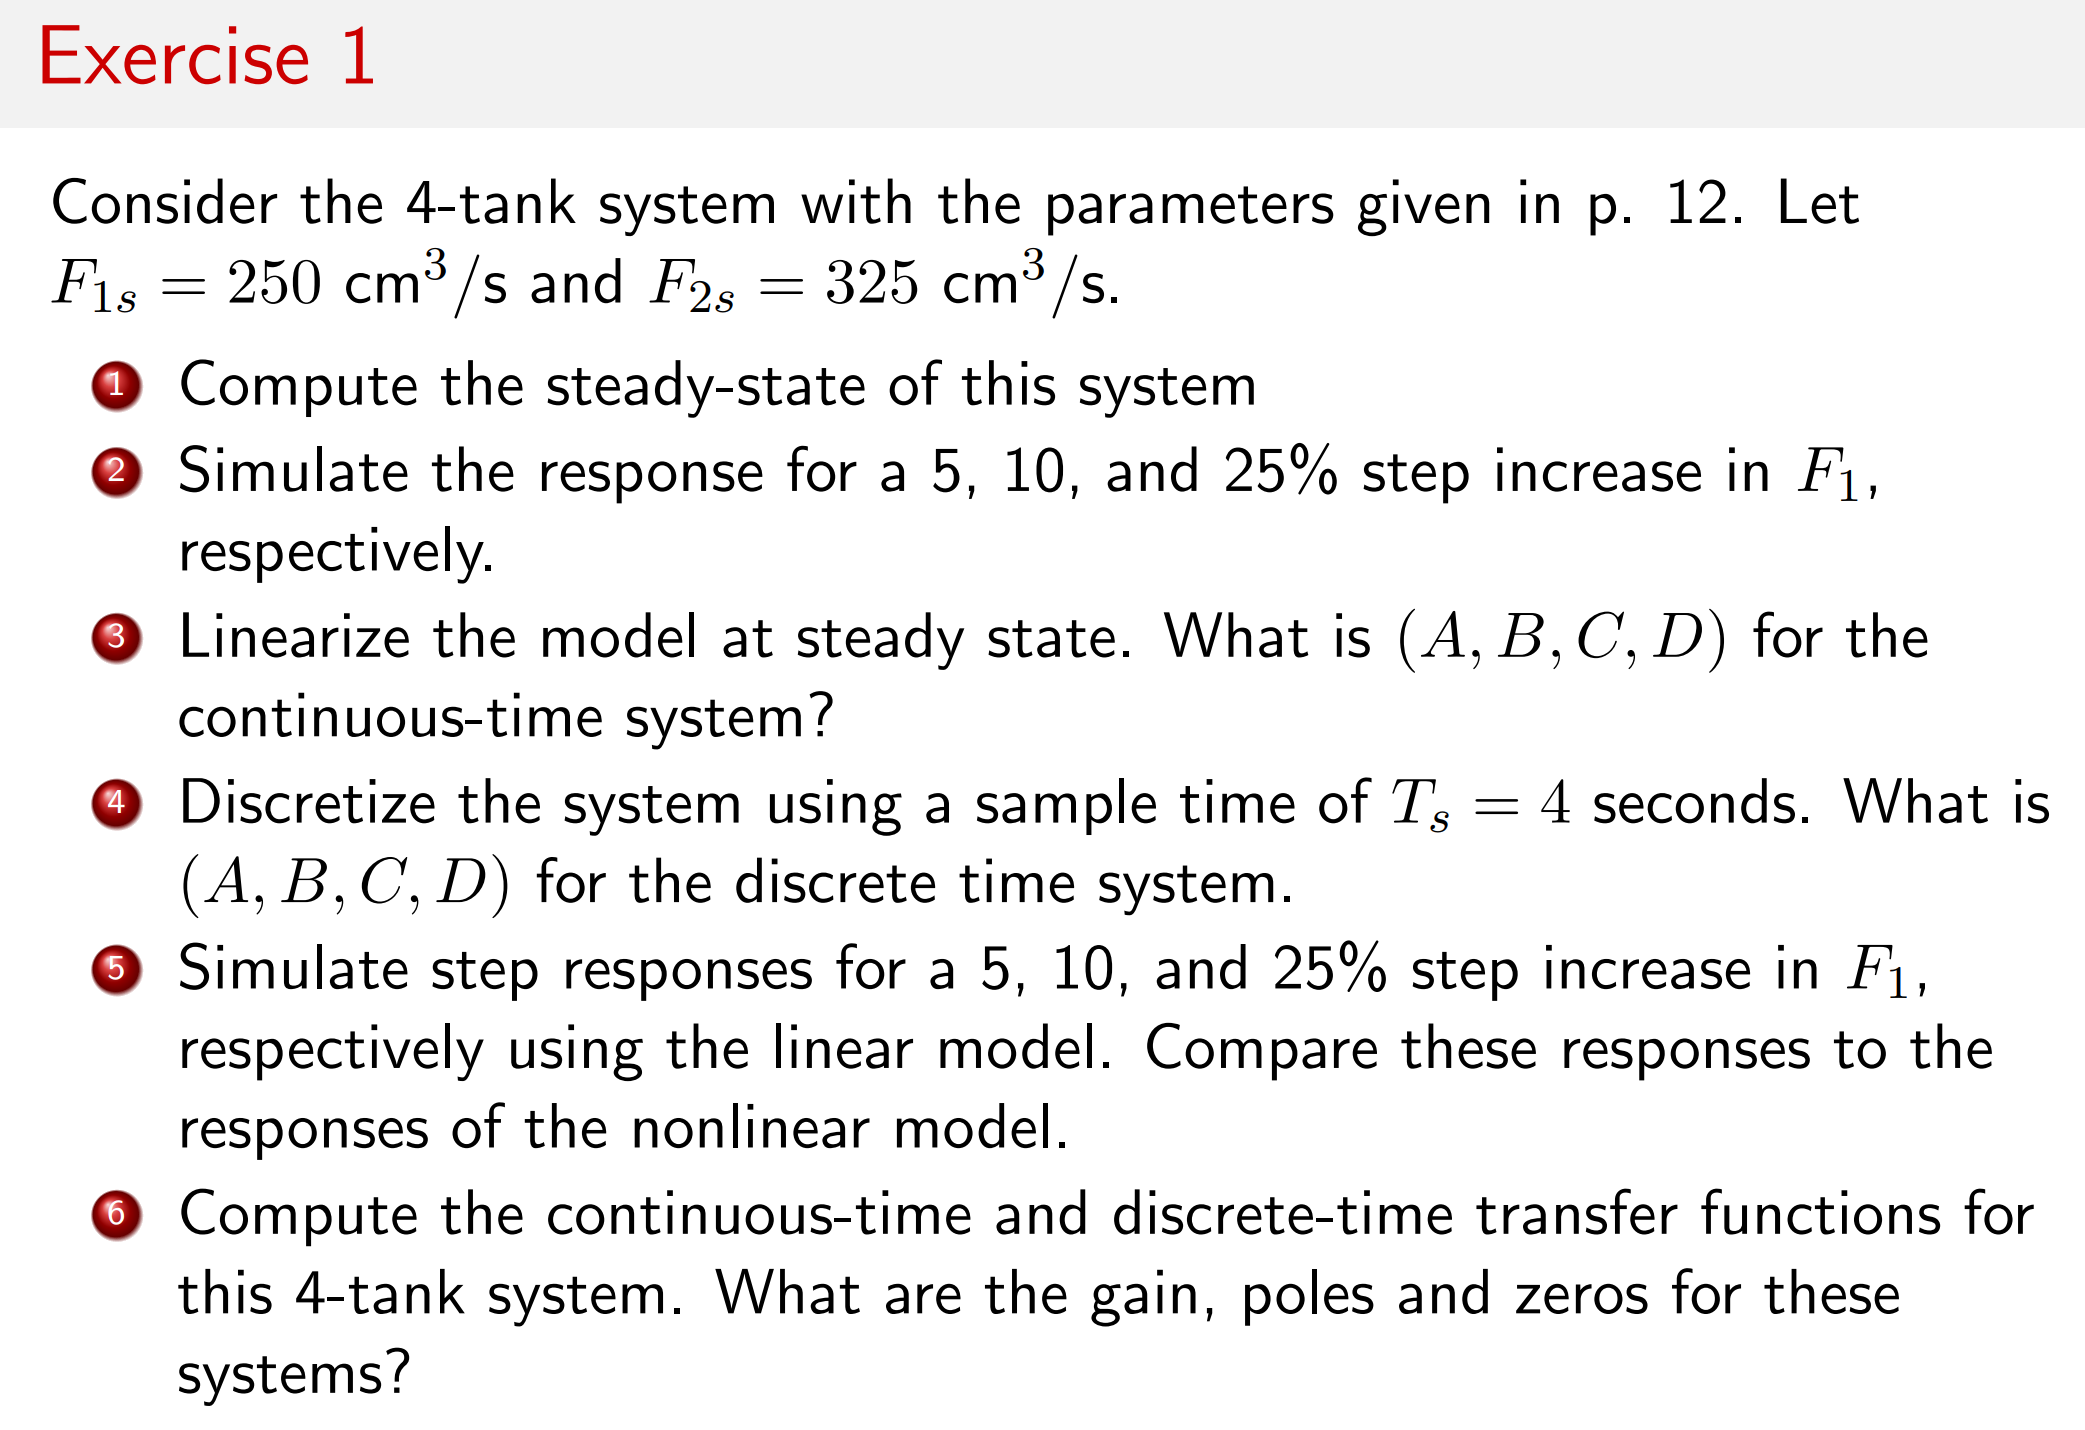

clear all;
% --------------------------------------------------------------
% Parameters
% --------------------------------------------------------------
a1 = 1.2272 %[cm2] Area of outlet pipe 1

a1 = 1.2272

a2 = 1.2272 %[cm2] Area of outlet pipe 2

a2 = 1.2272

a3 = 1.2272 %[cm2] Area of outlet pipe 3

a3 = 1.2272

a4 = 1.2272 %[cm2] Area of outlet pipe 4

a4 = 1.2272

A1 = 380.1327 %[cm2] Cross sectional area of tank 1

A1 = 380.1327

A2 = 380.1327 %[cm2] Cross sectional area of tank 2

A2 = 380.1327

A3 = 380.1327 %[cm2] Cross sectional area of tank 3

A3 = 380.1327

A4 = 380.1327 %[cm2] Cross sectional area of tank 4

A4 = 380.1327

gamma1 = 0.45; % Flow distribution constant. Valve 1
gamma2 = 0.40; % Flow distribution constant. Valve 2
g = 981; %[cm/s2] The acceleration of gravity
rho = 1.00; %[g/cm3] Density of water
p = [a1; a2; a3; a4; A1; A2; A3; A4; gamma1; gamma2; g; rho];
% --------------------------------------------------------------

%ex1.1 找稳态点，求解非线性方程就可以了，所以使用了fsolve
ap = [a1; a2; a3; a4]; % [cm2] Pipe cross sectional areas
At = [A1; A2; A3; A4]; % [cm2] Tank cross sectional areas
gam = [gamma1; gamma2]; % [-] Valve constants
g = 981; %[cm/s2] The acceleration of gravity
rho = 1.00; %[g/cm3] Density of water
p = [ap; At; gam; g; rho];
% --------------------------------------------------------------
% Steady State
% --------------------------------------------------------------
us = [250; 325]; % [cm3/s] Flow rates
xs0 = [5000; 5000; 5000; 5000]; % [g] Initial guess on xs
xs = fsolve(@FourTankSystemWrap,xs0,[],us,p)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


xs = 	1.0e+04 *

    1.2165
    0.9206
    0.4892
    0.2432


ys = FourTankSystemSensor(xs,p)

ys =    32.0008
   24.2169
   12.8688
    6.3985


zs = FourTankSystemOutput(xs,p)

zs =    32.0008
   24.2169


%ex1.2 进行非线性系统的仿真，要用离散的仿真 这里我们每十秒一个区间进行仿真
t0 = 0.0; % [s] Initial time
t_final = 20*60; % [s] Final time
Ts = 10; % [s] Sample Time
t = [t0:Ts:t_final]'; % [s] Sample instants
N = length(t);
m10 = 0; % [g] Liquid mass in tank 1 at time t0
m20 = 0; % [g] Liquid mass in tank 2 at time t0
m30 = 0; % [g] Liquid mass in tank 3 at time t0
m40 = 0; % [g] Liquid mass in tank 4 at time t0
F1 = 250; % [cm3/s] Flow rate from pump 1
F2 = 325; % [cm3/s] Flow rate from pump 2
x0 = [m10; m20; m30; m40];
%step 0.05
u_5 = [repmat(F1,1,N); repmat(F2,1,N)];
u_5(1,40:end)=F1*(1+0.05);
%step 0.1
u_10 = [repmat(F1,1,N); repmat(F2,1,N)];
u_10(1,40:end)=F1*(1+0.1);
%step 0.25
u_25 = [repmat(F1,1,N); repmat(F2,1,N)];
u_25(1,40:end)=F1*(1+0.25);
% --------------------------------------------------------------
nx = 4; nu = 2; ny = 4; nz = 2;
x = zeros(nx,N);
y = zeros(ny,N);
z = zeros(nz,N);
X = zeros(0,nx);
T = zeros(0,1);
x(:,1) = x0;
for k = 1:N-1
y(:,k) = FourTankSystemSensor(x(:,k),p); % Sensor function
z(:,k) = FourTankSystemOutput(x(:,k),p); % Output function
[Tk,Xk] = ode15s(@FourTankSystem,[t(k) t(k+1)],x(:,k),[],...
u_25(:,k),p);
x(:,k+1) = Xk(end,:)';
T = [T; Tk];
X = [X; Xk];
end
k = N;
y(:,k) = FourTankSystemSensor(x(:,k),p); % Sensor function
z(:,k) = FourTankSystemOutput(x(:,k),p); % Output function

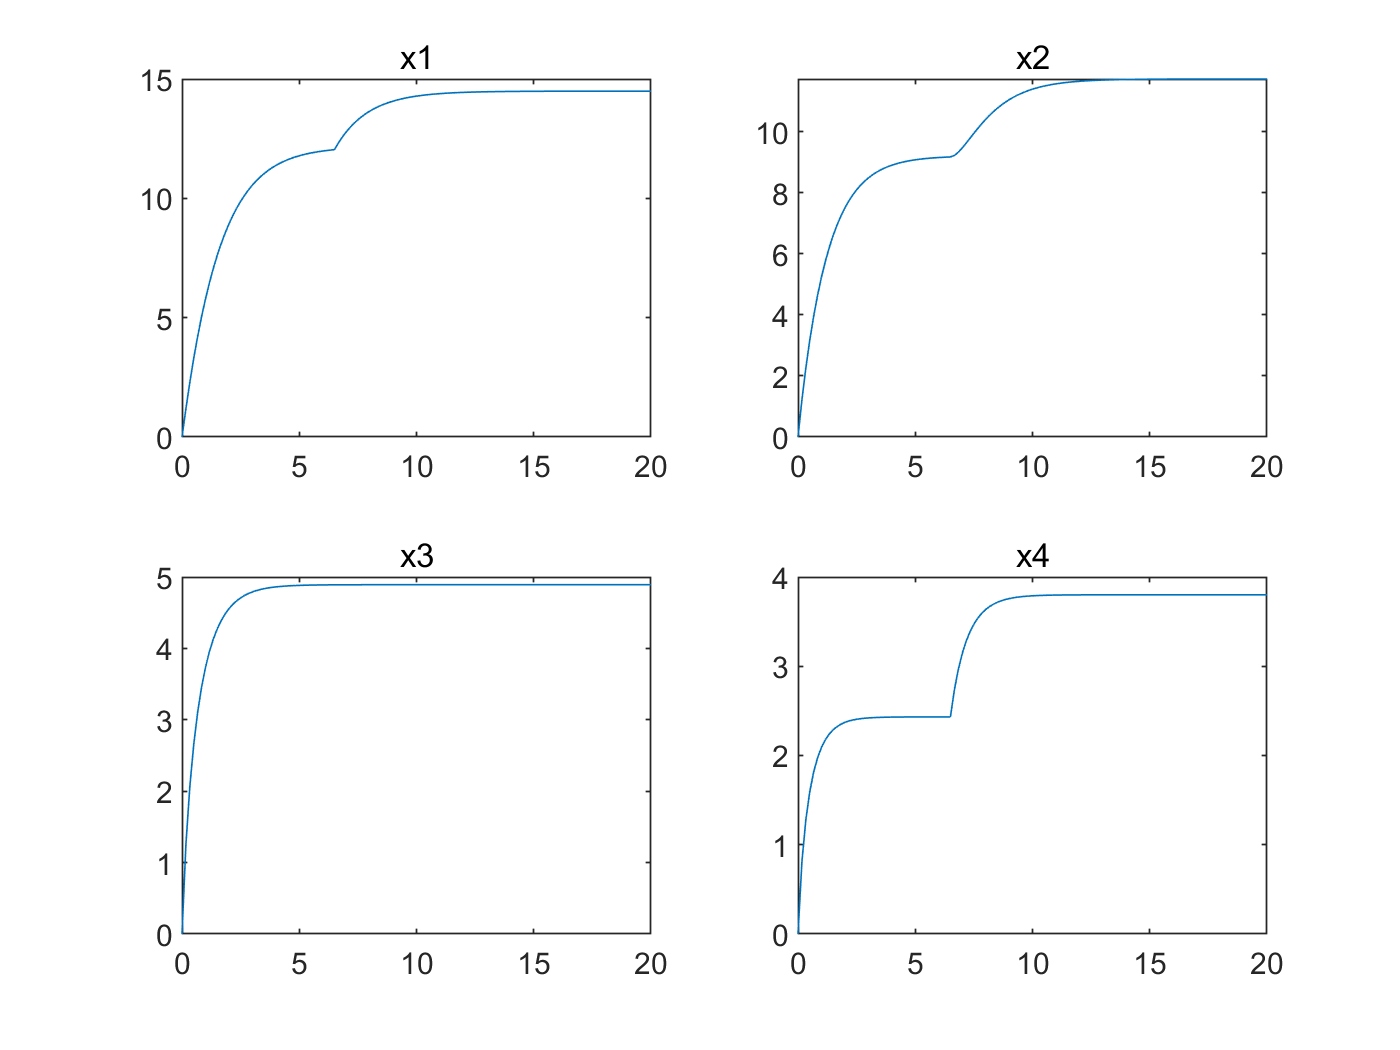

%ex1.2 plot x 
figure
subplot(2,2,1)
plot(t/60,x(1,:)/1e3)
title('x1')
subplot(2,2,2)
plot(t/60,x(2,:)/1e3)
title('x2')
subplot(2,2,3)
plot(t/60,x(3,:)/1e3)
title('x3')
subplot(2,2,4)
plot(t/60,x(4,:)/1e3)
title('x4')

%ex1.3 对非线性系统进行线性化，需要使用雅可比矩阵求导
syms x1 x2 x3 x4 u1 u2 
m = [x1;x2;x3;x4]; % Mass of liquid in each tank [g]
F = [u1;u2]; % Flow rates in pumps [cm3/s]
a = p(1:4,1); % Pipe cross sectional areas [cm2]
A = p(5:8,1); % Tank cross sectional areas [cm2]
gamma = p(9:10,1); % Valve positions [-]
g = p(11,1); % Acceleration of gravity [cm/s2]
rho = p(12,1); % Density of water [g/cm3]

% Inflows

qin(1,1) = gamma(1)*F(1); % Inflow from valve 1 to tank 1 [cm3/s]
qin(2,1) = gamma(2)*F(2); % Inflow from valve 2 to tank 2 [cm3/s]
qin(3,1) = (1-gamma(2))*F(2); % Inflow from valve 2 to tank 3 [cm3/s]
qin(4,1) = (1-gamma(1))*F(1); % Inflow from valve 1 to tank 4 [cm3/s]
% Out_finallows
h = m./(rho*A); % Liquid level in each tank [cm]
qout = a.*sqrt(2*g*h); % Out_finallow from each tank [cm3/s]
% Differential equations

fx(1,1) = rho*(qin(1,1)+qout(3,1)-qout(1,1)); % Mass balance Tank 1
fx(2,1) = rho*(qin(2,1)+qout(4,1)-qout(2,1)); % Mass balance Tank 2
fx(3,1) = rho*(qin(3,1)-qout(3,1)); % Mass balance Tank 3
fx(4,1) = rho*(qin(4,1)-qout(4,1)); % Mass balance Tank 4
gx = zeros(4,1);
gx = m./(rho*A);% Liquid level in each tank [cm]
Ass=eval(vpa(subs(jacobian(fx,m),[m;F],[xs;us]),4));
Bss=eval(vpa(subs(jacobian(fx,F),[m;F],[xs;us]),4));
Css=eval(vpa(subs(jacobian(gx,m),[m;F],[xs;us]),4));
Dss=eval(vpa(subs(jacobian(gx,F),[m;F],[xs;us]),4));

%ex1.4 线性系统的离散化
Ts = 4; 
[Ad,Bd]=c2dzoh(Ass,Bss,Ts);

%ex1.5 线性离散系统的step仿真
sys_ld=ss(Ad,Bd,Css,Dss,Ts);
t0 = 0.0; % [s] Initial time
t_final = 20*60; % [s] Final time
Ts = 10; % [s] Sample Time
t = [t0:Ts:t_final]'; % [s] Sample instants
N = length(t);
m10 = 0; % [g] Liquid mass in tank 1 at time t0
m20 = 0; % [g] Liquid mass in tank 2 at time t0
m30 = 0; % [g] Liquid mass in tank 3 at time t0
m40 = 0; % [g] Liquid mass in tank 4 at time t0
F1 = 250; % [cm3/s] Flow rate from pump 1
F2 = 325; % [cm3/s] Flow rate from pump 2
x0 = [m10; m20; m30; m40];
%step 0.05
u_5 = [repmat(F1,1,N); repmat(F2,1,N)];
u_5(1,40:end)=F1*(1+0.05);
%step 0.1
u_10 = [repmat(F1,1,N); repmat(F2,1,N)];
u_10(1,40:end)=F1*(1+0.1);
%step 0.25
u_25 = [repmat(F1,1,N); repmat(F2,1,N)];
u_25(1,40:end)=F1*(1+0.25);
[y_ld,t_ld,x_ld] = lsim(sys_ld,u_25',t,x0);%注意行列安排

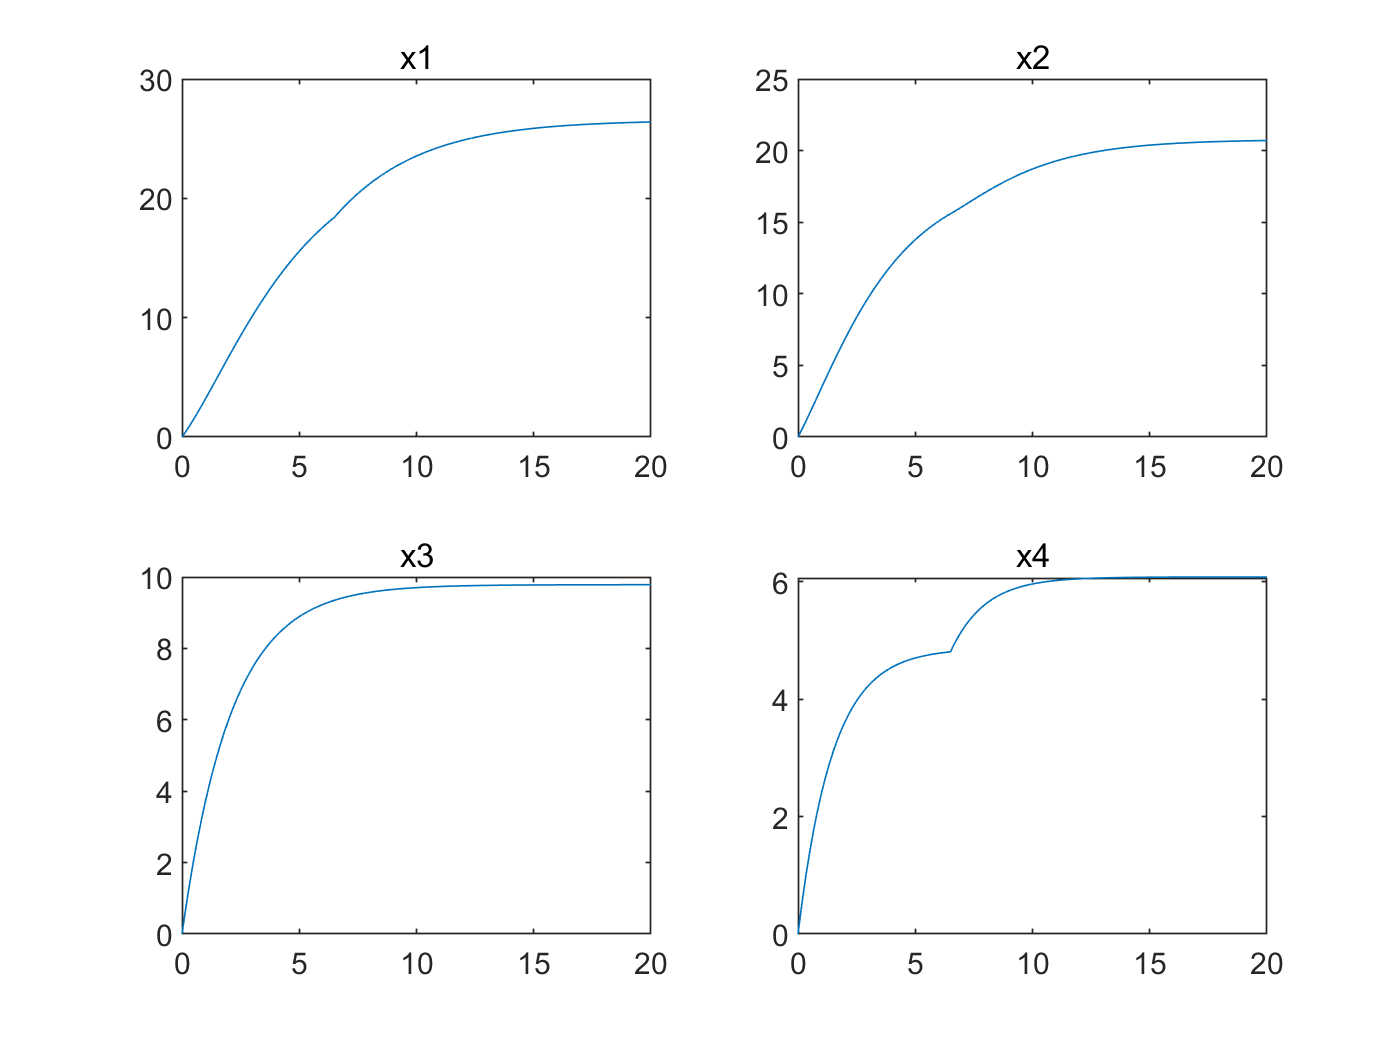

%ex1.5 plot x 
figure
subplot(2,2,1)
plot(t/60,x_ld(:,1)/1e3)
title('x1')
subplot(2,2,2)
plot(t/60,x_ld(:,2)/1e3)
title('x2')
subplot(2,2,3)
plot(t/60,x_ld(:,3)/1e3)
title('x3')
subplot(2,2,4)
plot(t/60,x_ld(:,4)/1e3)
title('x4')

%ex1.6 线性连续系统和线性离散系统的传递函数
Ts=4;
[num_c_F1,den_c_F1]=ss2tf(Ass,Bss,Css,Dss,1)

num_c_F1 =          0    0.0012    0.0001    0.0000    0.0000
         0         0    0.0000    0.0000    0.0000
         0         0         0         0         0
         0    0.0014    0.0001    0.0000    0.0000


den_c_F1 =     1.0000    0.0754    0.0021    0.0000    0.0000


[num_c_F2,den_c_F2]=ss2tf(Ass,Bss,Css,Dss,2)

num_c_F2 =          0         0    0.0000    0.0000    0.0000
         0    0.0011    0.0001    0.0000    0.0000
         0    0.0016    0.0001    0.0000    0.0000
         0         0         0         0         0


den_c_F2 =     1.0000    0.0754    0.0021    0.0000    0.0000


[num_d_F1,den_d_F1]=ss2tf(Ad,Bd,Css,Dss,1)

num_d_F1 =          0    0.0046   -0.0127    0.0117   -0.0036
         0    0.0003   -0.0003   -0.0003    0.0003
         0         0         0         0         0
         0    0.0055   -0.0154    0.0145   -0.0045


den_d_F1 =     1.0000   -3.7107    5.1625   -3.1915    0.7397


[num_d_F2,den_d_F2]=ss2tf(Ad,Bd,Css,Dss,2)

num_d_F2 =          0    0.0002   -0.0002   -0.0002    0.0002
         0    0.0041   -0.0113    0.0104   -0.0032
         0    0.0061   -0.0169    0.0157   -0.0049
         0         0         0         0         0


den_d_F2 =     1.0000   -3.7107    5.1625   -3.1915    0.7397


G_c_F1_x1=tf(num_c_F1(1,:),den_c_F1)

G_c_F1_x1 =
 
    0.001184 s^3 + 7.427e-05 s^2 + 1.496e-06 s + 9.692e-09
  ----------------------------------------------------------
  s^4 + 0.07537 s^3 + 0.002057 s^2 + 2.416e-05 s + 1.035e-07
 
Continuous-time transfer function.



G_d_F1_x1_test=c2d(G_c_F1_x1,Ts,'ZOH')

G_d_F1_x1_test =
 
  0.004618 z^3 - 0.01275 z^2 + 0.01172 z - 0.003593
  -------------------------------------------------
   z^4 - 3.711 z^3 + 5.162 z^2 - 3.191 z + 0.7397
 
Sample time: 4 seconds
Discrete-time transfer function.



G_d_F1_x1=tf(num_d_F1(1,:),den_d_F1,Ts)%same to con->dis

G_d_F1_x1 =
 
  0.004618 z^3 - 0.01275 z^2 + 0.01172 z - 0.003593
  -------------------------------------------------
   z^4 - 3.711 z^3 + 5.162 z^2 - 3.191 z + 0.7397
 
Sample time: 4 seconds
Discrete-time transfer function.



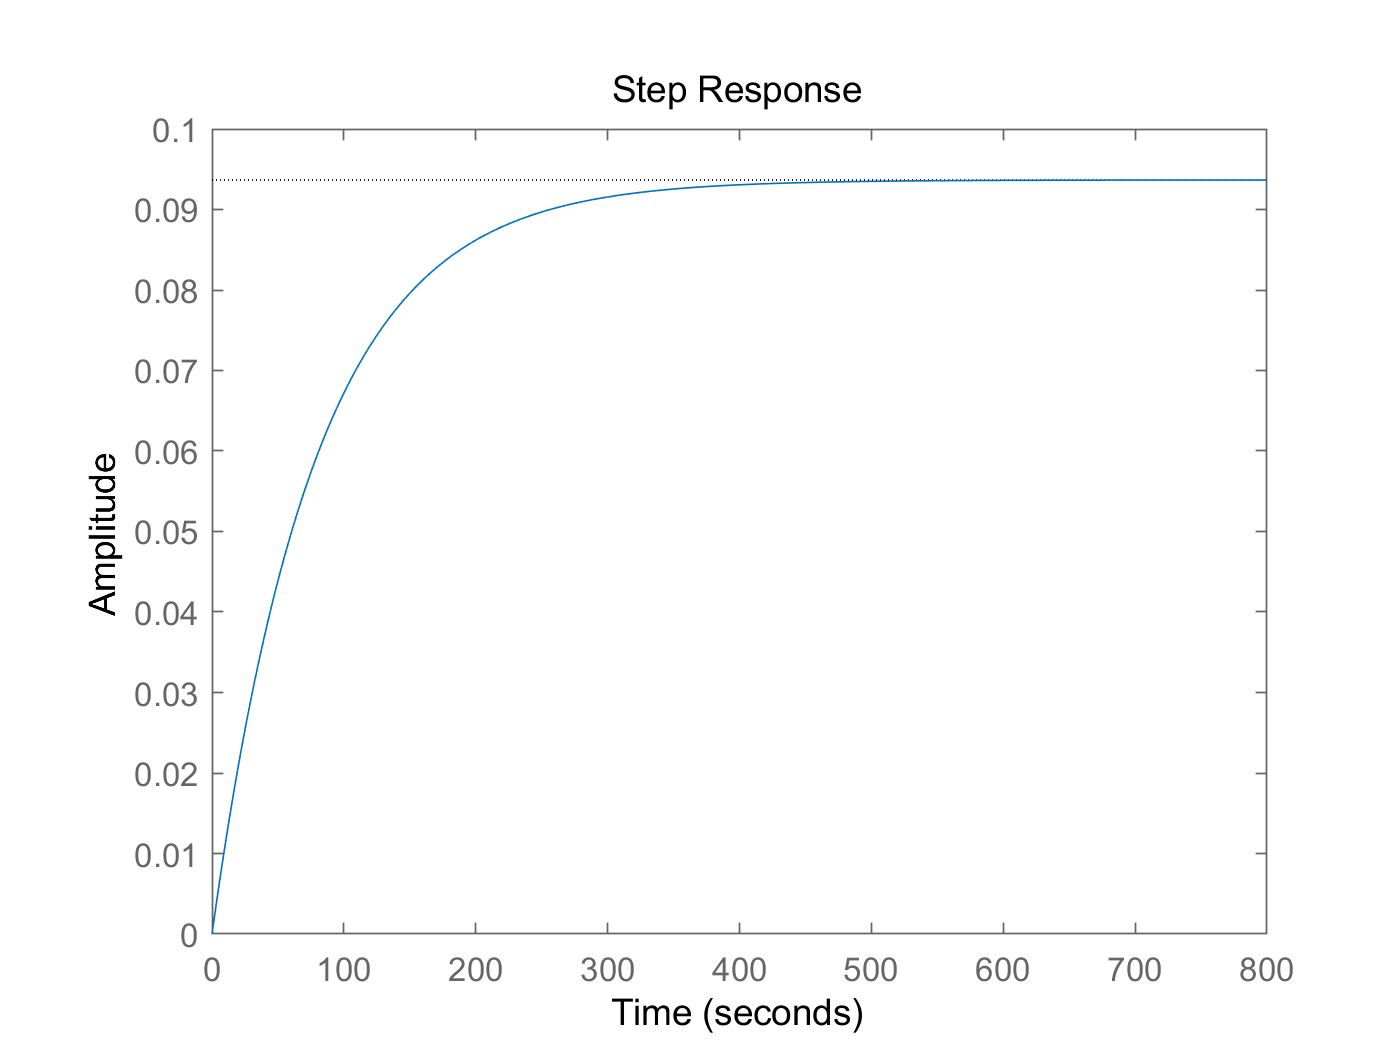

figure
step(G_c_F1_x1)

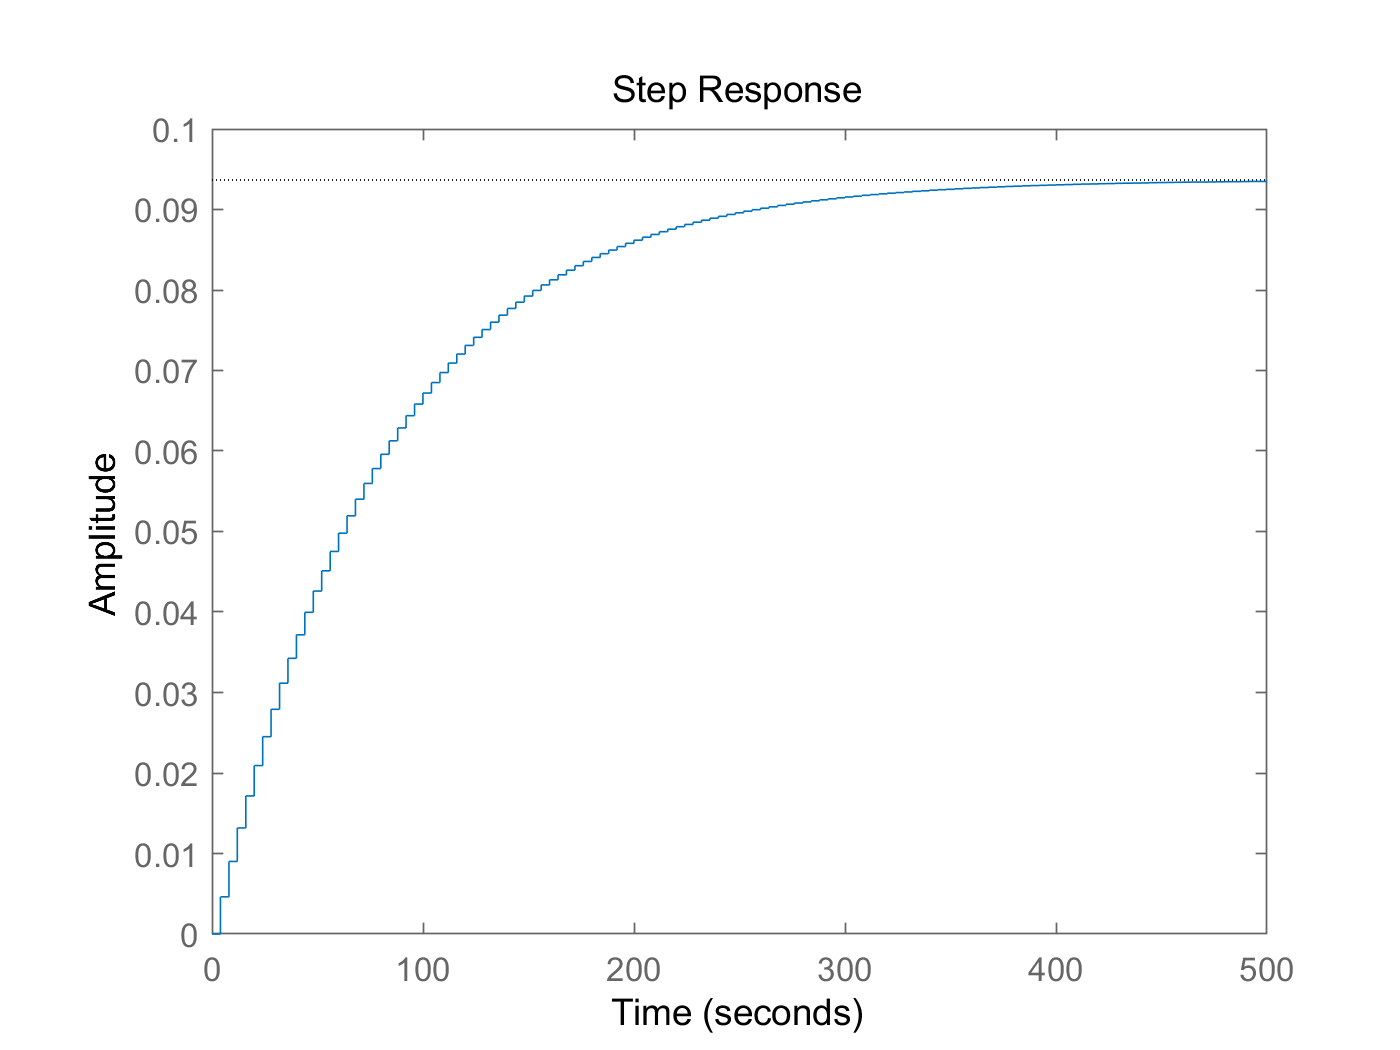

step(G_d_F1_x1_test)

step(G_d_F1_x1)


[z_1,p_1,k_1]=tf2zpk(cell2mat(G_c_F1_x1.Numerator),cell2mat(G_c_F1_x1.Denominator))

z_1 =    -0.0283
   -0.0199
   -0.0145


p_1 =    -0.0283
   -0.0199
   -0.0145
   -0.0126


k_1 = 0.0012

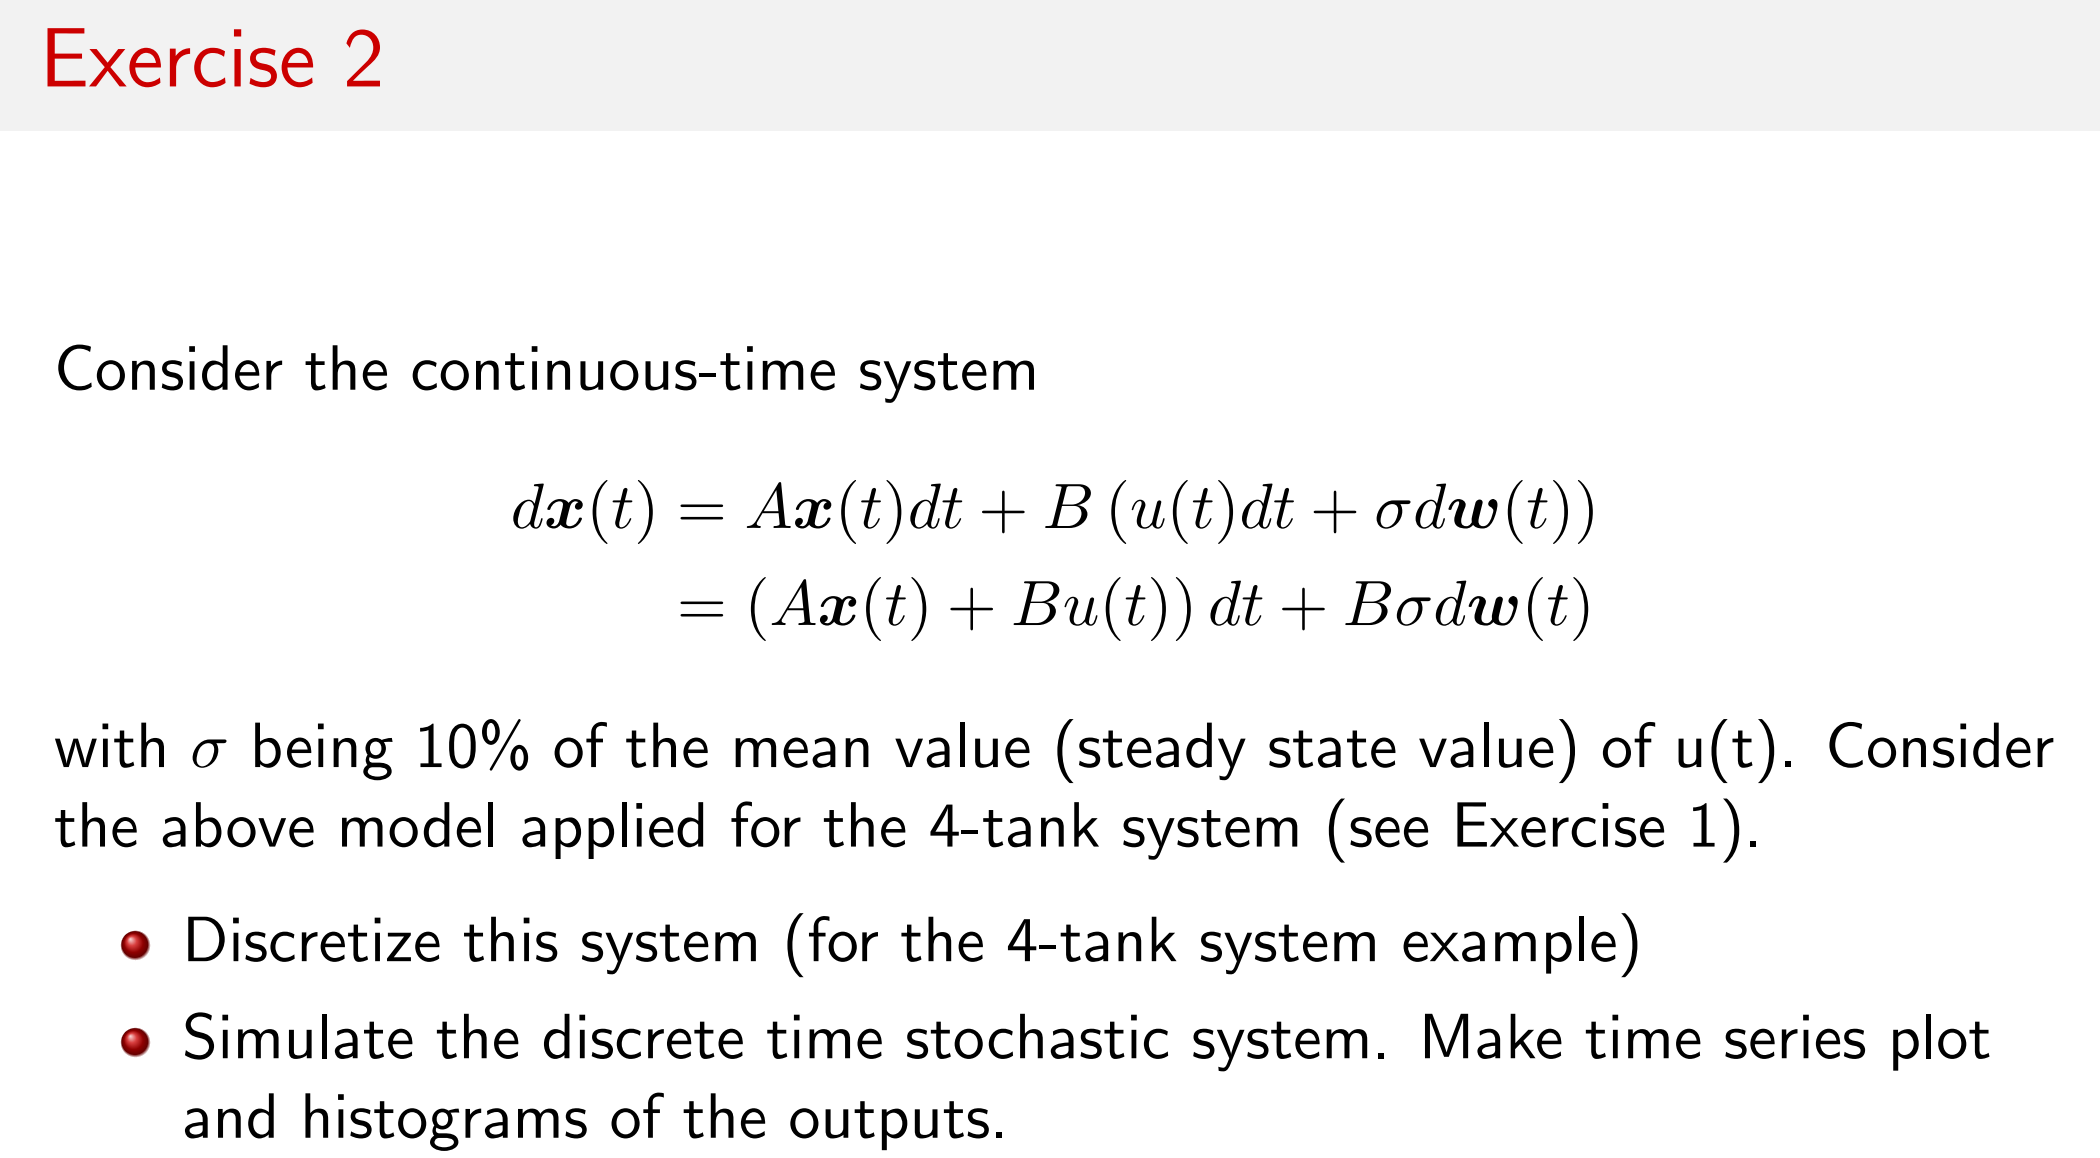

%ex2.1
%这里加入了随机的噪音，我们把它当作干扰
%要记住对于线性系统的离散化，如果假设干扰为0，则可离散u，若假设输入为0，则可离散d
%我们把u上的两个噪音作为单独的两个输入也加入input中，成为四个input，一起进行仿真
sigma=0.1

sigma = 0.1000

Bwss(:,1)=Bss(:,1)*us(1)*sigma

Bwss =    11.2500
         0
         0
   13.7500


Bwss(:,2)=Bss(:,2)*us(2)*sigma

Bwss =    11.2500         0
         0   13.0000
         0   19.5000
   13.7500         0


Ts = 4; 
[Ad,Bwd]=c2dzoh(Ass,Bwss,Ts)

Ad =     0.9507         0    0.0747         0
         0    0.9435         0    0.1038
         0         0    0.9234         0
         0         0         0    0.8931


Bwd =    43.8813    2.9774
    2.9380   50.5177
         0   74.9719
   52.0043         0


%ex2.2 对随机线性离散系统进行仿真 这里假设噪音为常数的白噪音
sys_ld_w=ss(Ad,[Bd Bwd],Css,[Dss zeros(4,2)],Ts);
t0 = 0.0; % [s] Initial time
t_final = 20*60; % [s] Final time
Ts = 10; % [s] Sample Time
t = [t0:Ts:t_final]'; % [s] Sample instants
N = length(t);
m10 = 0; % [g] Liquid mass in tank 1 at time t0
m20 = 0; % [g] Liquid mass in tank 2 at time t0
m30 = 0; % [g] Liquid mass in tank 3 at time t0
m40 = 0; % [g] Liquid mass in tank 4 at time t0
F1 = 250; % [cm3/s] Flow rate from pump 1
F2 = 325; % [cm3/s] Flow rate from pump 2
x0 = [m10; m20; m30; m40];
% Process Noise
Q = [20^2 0;0 40^2];
Lq = chol(Q,'lower');
w = Lq*sigma*randn(2,N);
%step 0.05
u_5 = [repmat(F1,1,N); repmat(F2,1,N)];
u_5(1,40:end)=F1*(1+0.05);
%step 0.1
u_10 = [repmat(F1,1,N); repmat(F2,1,N)];
u_10(1,40:end)=F1*(1+0.1);
%step 0.25
u_25 = [repmat(F1,1,N); repmat(F2,1,N)];
u_25(1,40:end)=F1*(1+0.25);
[y_ld,t_ld,x_ld] = lsim(sys_ld_w,[u_25;w]',t,x0);%注意行列安排

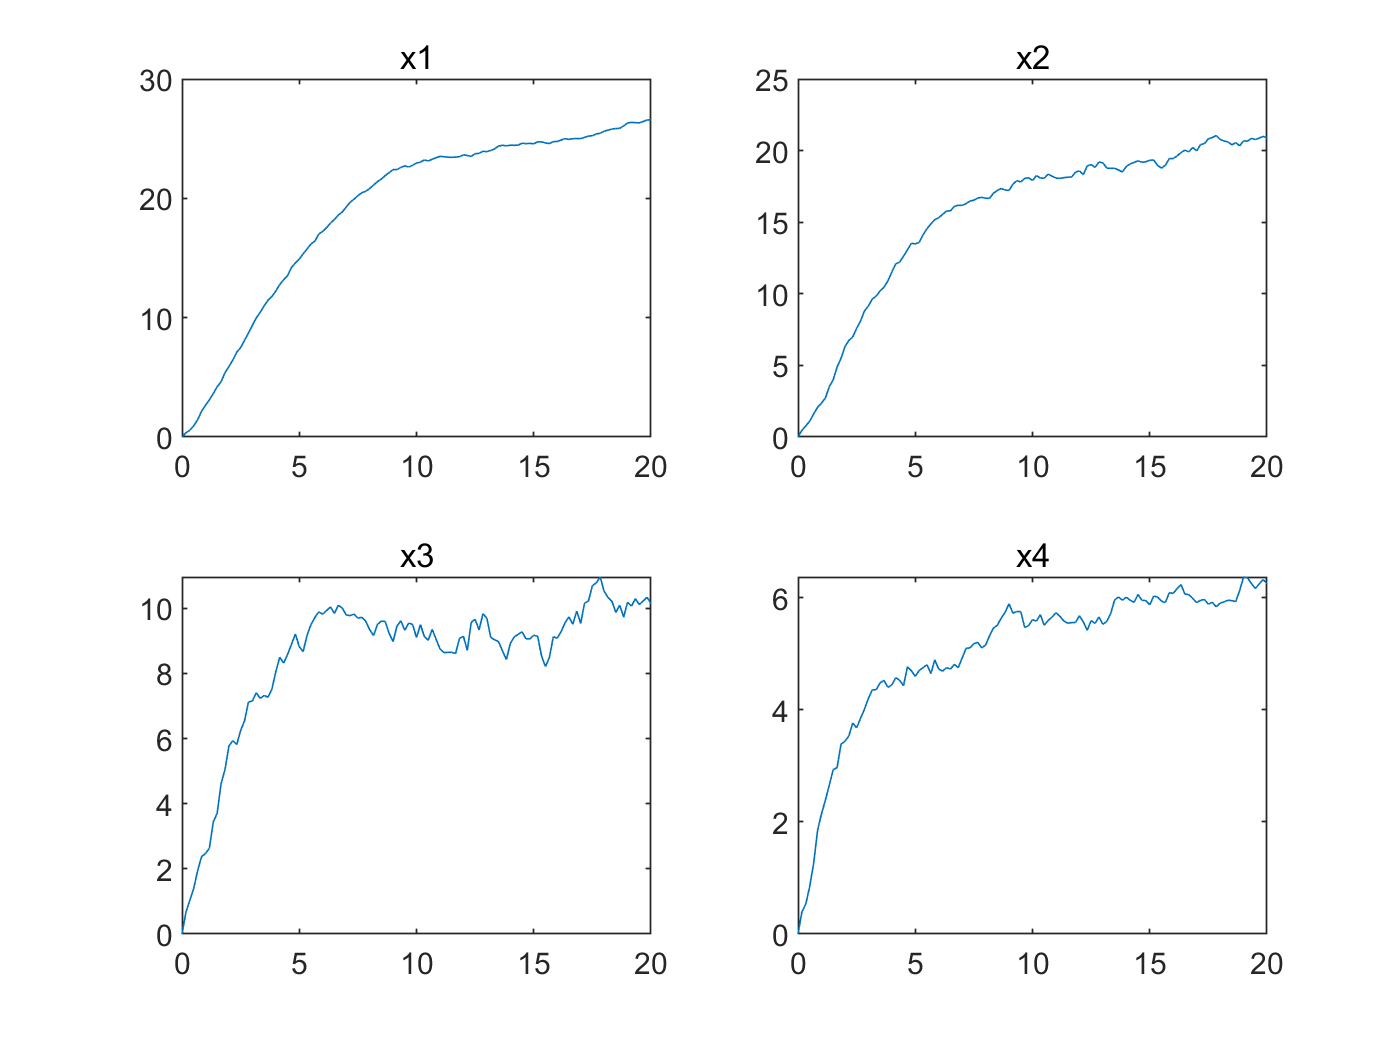

%ex2.2 plot x 
figure
subplot(2,2,1)
plot(t/60,x_ld(:,1)/1e3)
title('x1')
subplot(2,2,2)
plot(t/60,x_ld(:,2)/1e3)
title('x2')
subplot(2,2,3)
plot(t/60,x_ld(:,3)/1e3)
title('x3')
subplot(2,2,4)
plot(t/60,x_ld(:,4)/1e3)
title('x4')